% Quantizer Transfer Characteristics (Question 2.3)
clear; clc; close all;

% Parameters
Delta = 1;              % Step size
x = -4:0.001:4;         % Continuous input signal

% --- Calculate Quantized Outputs ---
% 1. Rounding (Identical for all 3 representations visually)
y_round = Delta * round(x / Delta);

% 2. Truncation: 2's Complement (Rounds towards -infinity)
y_trunc_2s = Delta * floor(x / Delta);

% 3. Truncation: Sign-Magnitude & 1's Complement (Rounds towards 0)
y_trunc_sm_1s = sign(x) .* Delta .* floor(abs(x) / Delta);

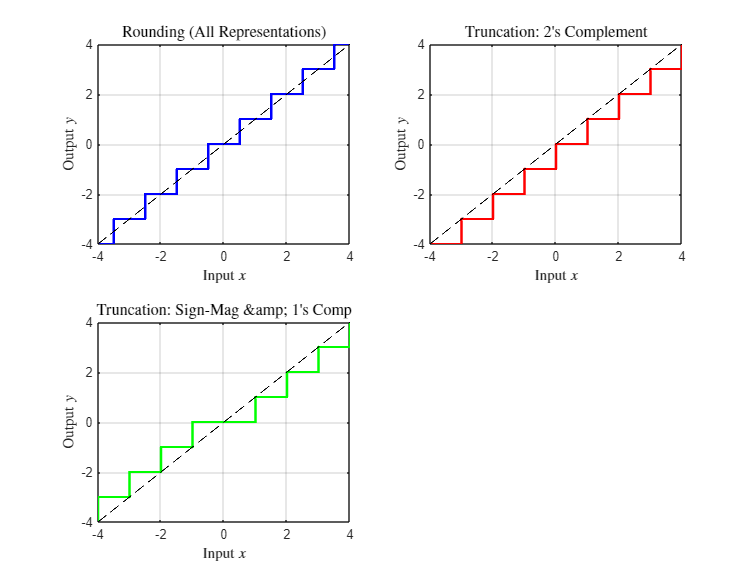


% --- Plotting ---
figure('Name', 'Quantizer Characteristics', 'Color', 'w', 'Position', [100, 100, 900, 700]);

% Plot 1: Rounding (All representations)
subplot(2, 2, 1);
plot(x, y_round, 'b', 'LineWidth', 2);
hold on; plot(x, x, 'k--', 'LineWidth', 1); % Ideal linear line for reference
title('Rounding (All Representations)', 'Interpreter', 'latex', 'FontSize', 12);
xlabel('Input $x$', 'Interpreter', 'latex');
ylabel('Output $y$', 'Interpreter', 'latex');
grid on; axis([-4 4 -4 4]);

% Plot 2: Truncation in 2's Complement
subplot(2, 2, 2);
plot(x, y_trunc_2s, 'r', 'LineWidth', 2);
hold on; plot(x, x, 'k--', 'LineWidth', 1); 
title('Truncation: 2''s Complement', 'Interpreter', 'latex', 'FontSize', 12);
xlabel('Input $x$', 'Interpreter', 'latex');
ylabel('Output $y$', 'Interpreter', 'latex');
grid on; axis([-4 4 -4 4]);

% Plot 3: Truncation in Sign-Magnitude & 1's Complement
subplot(2, 2, 3.5); % Centered on the bottom row
plot(x, y_trunc_sm_1s, 'g', 'LineWidth', 2);
hold on; plot(x, x, 'k--', 'LineWidth', 1); 
title('Truncation: Sign-Mag \& 1''s Comp', 'Interpreter', 'latex', 'FontSize', 12);
xlabel('Input $x$', 'Interpreter', 'latex');
ylabel('Output $y$', 'Interpreter', 'latex');
grid on; axis([-4 4 -4 4]);